## A MATLAB Live Script  for the MA378 class on piecewise interpolation

Picewise polynomial interpolation examples. 

NOTE: The version of "pchip" used here is not the same as in class: it doesn't use 

$f'(x)$and so is less accurate. But it is still monotone.

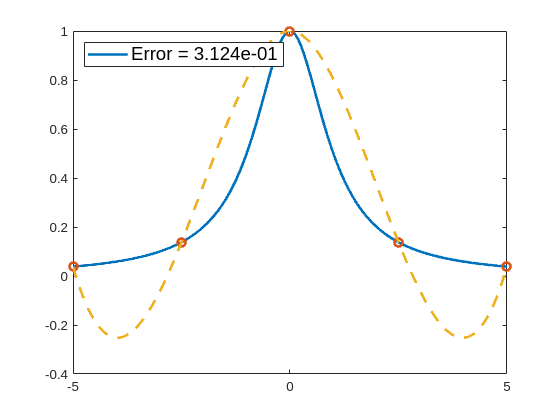

a=-5; b=5;
f = @(x)1./(1+x.^2);
n=4;
xp = linspace(a,b,n+1);
l = @(x)spline(xp, f(xp), x);
X = linspace(a,b,1001);
Error = max(f(X)-l(X));
plot(X, f(X), xp, f(xp), 'o', X, l(X), '--', ...
   'LineWidth',2);
legend(sprintf("Error = %8.3e", Error), 'FontSize',14, location='northwest');